syms theta1(t) theta2(t) l1 l2 x(t) y(t) m1 m2
g = 9.8;

xy =  [l1*cosd(theta1) l1*cosd(theta1) + l2*cosd(theta2);
      l1*sind(theta1) l1*sind(theta1) + l2*sind(theta2);];         %Forward Kinematics 
xy_a = xy(t);
disp(xy);

$$\left(\begin{array}{cc} l_{1}\,\cos\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right) & l_{1}\,\cos\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right)+l_{2}\,\cos\left(\frac{\pi \,\theta_{2}\left(t\right)}{180}\right)\\ l_{1}\,\sin\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right) & l_{1}\,\sin\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right)+l_{2}\,\sin\left(\frac{\pi \,\theta_{2}\left(t\right)}{180}\right) \end{array}\right)$$

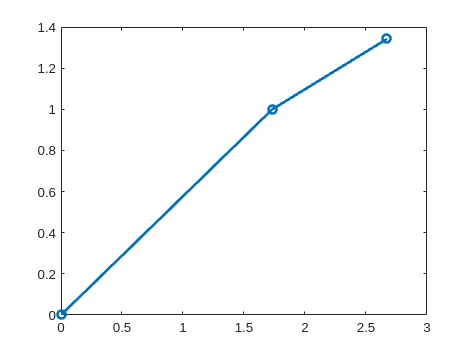

coords = subs(xy,{l1,l2,theta1,theta2},{2,1,30,20});               %Substituting the joint values and link lengths
coords = double(coords);
plot([0 coords(1,1:2)],[0 coords(2,1:2)],'-o',LineWidth=2);        %Plot

xy_dot = diff(xy,t);                                               %Vel Matrix         
disp('The velocity matrix: ');

The velocity matrix: 


disp(xy_dot);

$$\begin{array}{l} \left(\begin{array}{cc} -\frac{\pi \,l_{1}\,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180} & -\frac{l_{1}\,\pi \,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}-\frac{l_{2}\,\pi \,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\\ \frac{\pi \,l_{1}\,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180} & \frac{l_{1}\,\pi \,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\theta_{2}\left(t\right)}{180}\\ \sigma_{2}=\frac{\pi \,\theta_{1}\left(t\right)}{180} \end{array}$$

a= xy_dot(t);

v1 = sqrt((a(1,1)^2 + a(2,1)^2));
v2 = sqrt((a(1,2)^2 + a(2,2)^2));
disp('v1:');

v1:


disp(v1);

$$\sqrt{\frac{\pi^{2}\,{l_{1}}^{2}\,{\sin\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{32400}+\frac{\pi^{2}\,{l_{1}}^{2}\,{\cos\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{32400}}$$

disp('v2:');

v2:


disp(v2);

$$\begin{array}{l} \sqrt{{\left(\frac{l_{1}\,\pi \,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\right)}^{2}+{\left(\frac{l_{1}\,\pi \,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi \,\theta_{2}\left(t\right)}{180}\\ \sigma_{2}=\frac{\pi \,\theta_{1}\left(t\right)}{180} \end{array}$$

## LAGRANGIAN

kin_erg_m1 = 1/2 * m1 * (v1^2);
kin_erg_m2 = 1/2 * m2 * (v2^2);

total_kin_erg = kin_erg_m1 + kin_erg_m2;
disp('Total Kinetic Energy: ');

Total Kinetic Energy: 


disp(total_kin_erg);

$$\begin{array}{l} \frac{m_{2}\,\left({\left(\frac{l_{1}\,\pi \,\cos\left(\sigma_{3}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\right)}^{2}+{\left(\frac{l_{1}\,\pi \,\sin\left(\sigma_{3}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\right)}^{2}\right)}{2}+\frac{m_{1}\,\left(\frac{\pi^{2}\,{l_{1}}^{2}\,{\sin\left(\sigma_{3}\right)}^{2}\,\sigma_{1}}{32400}+\frac{\pi^{2}\,{l_{1}}^{2}\,{\cos\left(\sigma_{3}\right)}^{2}\,\sigma_{1}}{32400}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\pi \,\theta_{2}\left(t\right)}{180}\\ \sigma_{3}=\frac{\pi \,\theta_{1}\left(t\right)}{180} \end{array}$$

pot_erg_1 = m1 * g * xy_a(2,1);
pot_erg_2 = m2 * g * xy_a(2,2);

total_pot_erg = pot_erg_1 + pot_erg_2;
disp('Total Potential Energy: ');

Total Potential Energy: 


disp(total_pot_erg);

$$\frac{49\,m_{2}\,\left(l_{1}\,\sin\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right)+l_{2}\,\sin\left(\frac{\pi \,\theta_{2}\left(t\right)}{180}\right)\right)}{5}+\frac{49\,l_{1}\,m_{1}\,\sin\left(\frac{\pi \,\theta_{1}\left(t\right)}{180}\right)}{5}$$

lagrangian = total_kin_erg - total_pot_erg;
disp('Lagrangian: ');

Lagrangian: 


lagrangian

$$lagrangian = \begin{array}{l} \frac{m_{2}\,\left({\left(\frac{l_{1}\,\pi \,\cos\left(\sigma_{3}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\cos\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\right)}^{2}+{\left(\frac{l_{1}\,\pi \,\sin\left(\sigma_{3}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{180}+\frac{l_{2}\,\pi \,\sin\left(\sigma_{2}\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{180}\right)}^{2}\right)}{2}-\frac{49\,m_{2}\,\left(l_{1}\,\sin\left(\sigma_{3}\right)+l_{2}\,\sin\left(\sigma_{2}\right)\right)}{5}+\frac{m_{1}\,\left(\frac{\pi^{2}\,{l_{1}}^{2}\,{\sin\left(\sigma_{3}\right)}^{2}\,\sigma_{1}}{32400}+\frac{\pi^{2}\,{l_{1}}^{2}\,{\cos\left(\sigma_{3}\right)}^{2}\,\sigma_{1}}{32400}\right)}{2}-\frac{49\,l_{1}\,m_{1}\,\sin\left(\sigma_{3}\right)}{5}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\pi \,\theta_{2}\left(t\right)}{180}\\ \sigma_{3}=\frac{\pi \,\theta_{1}\left(t\right)}{180} \end{array}$$

# %EULER - LAGRANGIAN EQUATION

% For Link 1

% dt_dot1 = dL/d(theta1_dot)
dl_1 = diff(lagrangian,theta1);
dt_dot1 = diff(lagrangian,diff(theta1));
t1 = diff(dt_dot1,t) - dl_1;

disp(t1);

% For Link 2

% dt_dot2 = dL/d(theta2_dot)
dl_2 = diff(lagrangian,theta2);
dt_dot2 = diff(lagrangian,diff(theta2));
t2 = diff(dt_dot2,t) - dl_2;

disp(t2);